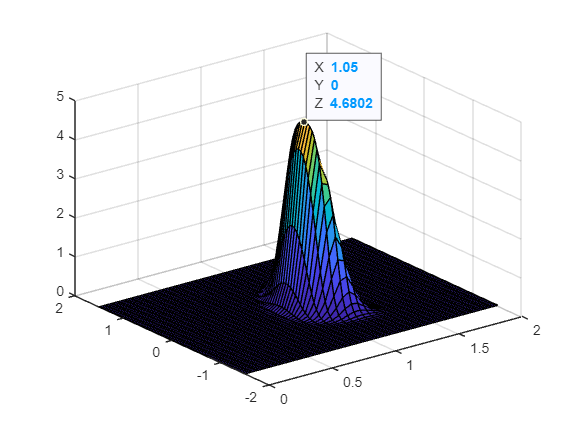

%prior probability

mu = [1.08 0];
Sigma = [0.01 0; 0 .131];

x1 = 0:.05:2;
x2 = -1.5:.05:1.5;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)];

P = mvnpdf(X,mu,Sigma);
P = reshape(P,length(x2),length(x1));

%uniformative likelihood

sigma = 0.1;
x=0:.05:2;
y=-1.5:.05:1.5;
[X,Y] = meshgrid(x,y); 
F = (1/sqrt((2*pi)*sigma))*exp(-(1-(X.*cos(Y))).^2 / (2*sigma^2));

%posterior 

Z = P.*F;

surf(X1,X2,Z)